## ECG Signal Processing

### Loading the File Containing the ECG Signal

load ecg_data.dat -ascii;

### Setting Parameters of the ECG Signal

fs = 1000; % Sampling frequency (Hz)
ts = 1 / fs; % Sampling period (s)
t = (0:(length(ecg_data) - 1)) * ts; % Time vector


### Plotting the Time Domain Graph of the Original ECG Signal

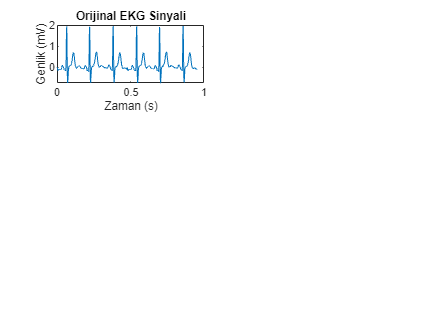

figure;
subplot(3, 2, 1);
plot(t, ecg_data);
title('Original ECG Signal');
xlabel('Time (s)');
ylabel('Amplitude (mV)');

### Calculating Frequency Components of ECG Signal

frequencies = linspace(0, fs/2, floor(length(ecg_data)/2) + 1); % Positive frequency components


### Plotting Frequency Domain Graph of ECG Signal

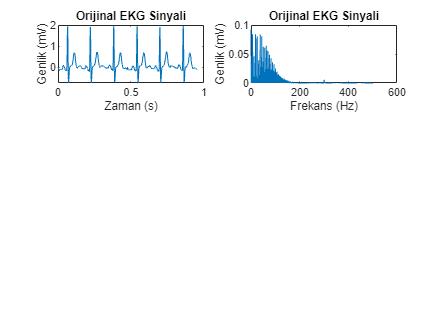

fft_ecg_data = abs(fft(ecg_data) / length(ecg_data)); % Calculating FFT of the original ECG signal and normalizing it

subplot(3, 2, 2);
plot(frequencies, fft_ecg_data(1:floor(length(ecg_data) / 2) + 1)); % Plotting the frequency domain graph of the original ECG signal
title('Original ECG Signal');
xlabel('Frequency (Hz)');
ylabel('Amplitude (mV)');

### Creating Noise Signals

low_frequency_noise = zeros(size(t));
for f = 0.00:0.001:0.05 % Frequencies in 0.001 Hz intervals
    low_frequency_noise = low_frequency_noise + sin(2 * pi * f * t) .* (0.05 * rand(size(t))); % Low frequency noise, below 0.05 Hz
end

high_frequency_noise = zeros(size(t));
for f = 150:1:500 % Frequencies in 1 Hz intervals
    high_frequency_noise = high_frequency_noise + sin(2 * pi * f * t) .* (0.05 * rand(size(t))); % High frequency noise, above 150 Hz
end

mains_noise = sin(2 * pi * 50 * t) .* (0.1 * rand(size(t))); % Mains noise (50 Hz)


### Generating the Noisy ECG Signal

ecg_data_noisy = ecg_data + low_frequency_noise + high_frequency_noise + mains_noise; % Noisy ECG signal


### Plotting Time Domain Graph of Noisy ECG Signal

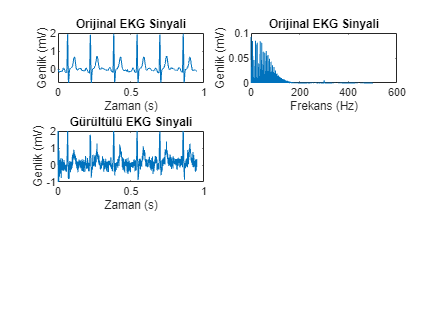

subplot(3, 2, 3);
plot(t, ecg_data_noisy);
ylim([-1 2]);
title('Noisy ECG Signal');
xlabel('Time (s)');
ylabel('Amplitude (mV)');

### Plotting Frequency Domain Graph of Noisy ECG Signal

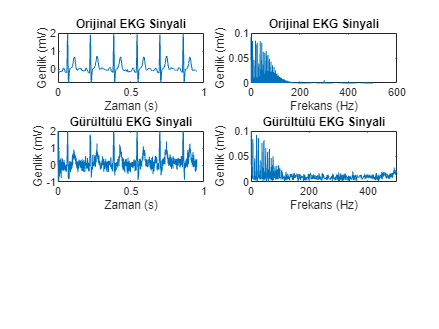

fft_ecg_data_noisy = abs(fft(ecg_data_noisy) / length(ecg_data_noisy)); % Calculating FFT of the noisy ECG signal and normalizing it

subplot(3, 2, 4);
plot(frequencies, fft_ecg_data_noisy(1:floor(length(ecg_data_noisy) / 2) + 1)); % Plotting the frequency domain graph of a noisy ECG signal
xlim([0 500]);
ylim([0 0.1]);
title('Noisy ECG Signal');
xlabel('Frequncy (Hz)');
ylabel('Amplitude (mV)');

### Saving Noisy ECG Signal

writematrix([t' ecg_data_noisy'], 'ecg_data_noisy.txt', 'Delimiter', '\t');


### 'ecg_data_noisy.txt' file will be given as input signal to 'filter.asc', 'filter.txt' must be exported as the output signal

### Reading Filtered ECG Signal

ecg_data_filtered = readmatrix('filter.txt');


### Setting Parameters of the ECG Signal

ts_filtered = mean(diff(ecg_data_filtered(:, 1)));
fs_filtered = 1/ts_filtered;
t_filtered = ecg_data_filtered(:, 1);


### Plotting the Time Domain of Filtered ECG Signal

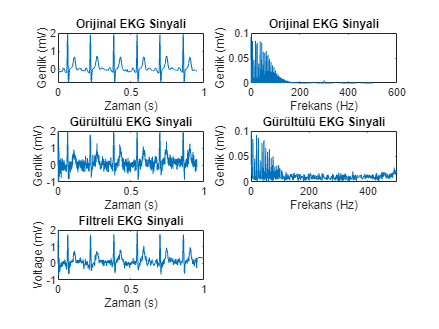

subplot(3, 2, 5);
plot(t_filtered, ecg_data_filtered(:,2));
ylim([-1 2]);
title('Filtered ECG Signal');
xlabel('Time (s)');
ylabel('Amplitude (mV)');

### Calculating Frequency Components of Filtered ECG Signal

frequencies_filtered = linspace(0, fs_filtered/2, floor(length(t_filtered)/2) + 1); % Positive frequency components


### Plotting the Frequency Domain Graph of the Filtered ECG Signal

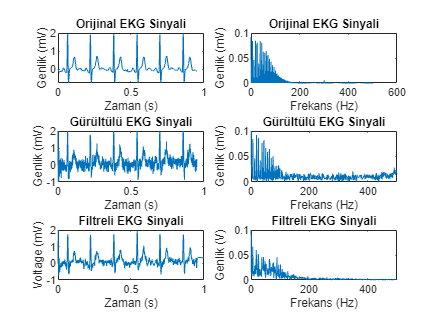

fft_ecg_data_filtered= abs(fft(ecg_data_filtered(:, 2)) / length(t_filtered)); % Calculating FFT of the filtered ECG signal and normalizing it

subplot(3, 2, 6);
plot(frequencies_filtered, fft_ecg_data_filtered(1:floor(length(t_filtered) / 2) + 1)); % Plotting the Frequency Domain Graph of the Filtered ECG Signal
xlim([0 500]);
ylim([0 0.1]);
title('Filtered ECG Signal');
xlabel('Frequency (Hz)');
ylabel('Amplitude (V)');

### Time Domain Co-Display of Original ECG Signal and Filtered ECG Signal

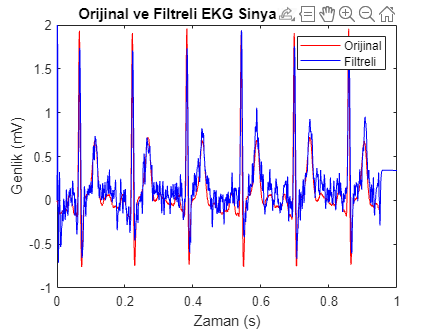

figure;
plot(t, ecg_data, 'r', t_filtered, ecg_data_filtered(:,2), 'b');
title('Original and Filtered ECG Signal Time Domain Graph');
legend('Original ECG', 'Filtered ECG');
ylim([-1 2]);
xlabel('Time (s)');
ylabel('Amplitude (mV)');